# TSoG-X1

# 3D Wing Aerodynamics Analysis

## Overview

In this analysis, I want to go over the concepts, assumptions, and methods used to determine the aerodynamic properties of the X1's wings:

- Geometry of the wing

- 2D Airfoil

- Lifting Line Theory

- Assumptions

- Algorithm

## Geometry of the wing

The shape of the wing is by far the most important aspect of the wing that determines how it will behave in flight. In this section we will explore how we will go about generating the geometry of the 3D wing and gain some 2D Airfoil data along the span of the wing.

### Terminology

 Here is a very useful diagram from NASA on terminology of wing geometry that we will be using throughout this analysis:

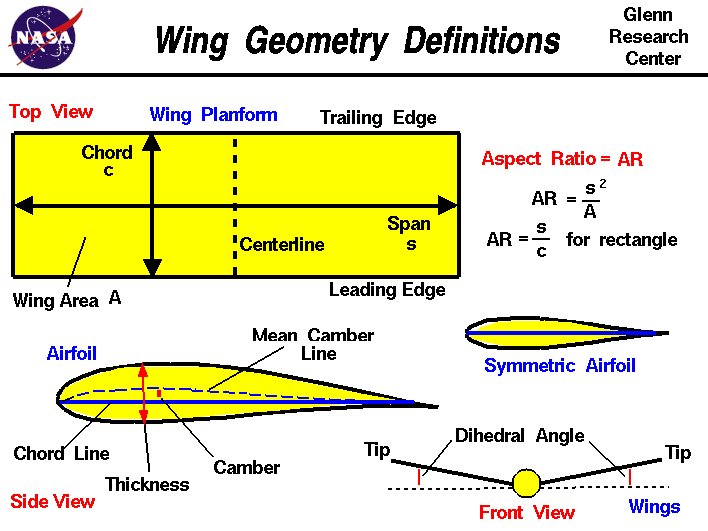

To help explain the diagram above, here are some definitions of the terminology to cement their meaning:

- **Span -** Length of a wing from tip to tip (think of a bird's wing tips)

- **Airfoil -** The cross sectional view of a wing viewed from it's side

- **Leading Edge -** The front most point of a wing (front is towards the direction of motion, in this case on the diagram the wing is flying to the left in the side view)

- **Trailing Edge -** The tip of the end of the wing

- **Chord Line -** A line connecting the Leading and Trailing Edges (this cuts the airfoil into an upper surface and lower surface)

- **Chord -** An alias for "Length of the Chord Line", variable is usually `c.`

- **Wing Area -** The area of the wing as seen from the top

- **Aspect Ratio -** The ratio between the span of a wing squared to the Wing Area (Examples: A fighter jet, like an F-16, has a small Aspect Ratio compared to a passenger jet, like a B737)

- **Thickness (of an airfoil) - **This is measured by the distance from the top of the wing to the bottom of the wing from the chord line

- **Mean Camber Line -** If you create a series of points that is the average distance from upper surface to the bottom surface, you will create a Mean Camber Line

- **Camber -** This is the distance between the Chord Line and the Mean Camber Line

In order to make this analysis both more generalized and easier, most distances will be measured as percentages of the Chord of the airfoil.

### Material Considerations for Wing Design

The wings of the X1 will be made by using foam board that is cut and bent over itself to create an enclosed shape such as the one below:

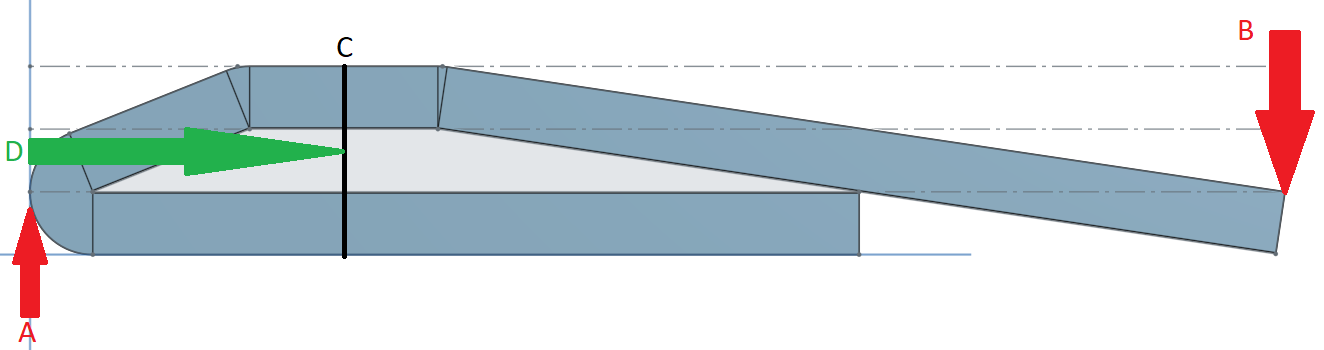

Where the markers indicate:

    A = Leading Edge

    B = Trailing Edge

    C = Max Camber Location of the Airfoil

    D = Distance to Max Camber (set to 25% of the Chord length)

The bottom of the airfoil is where the fuselage of the airplane will be glued to the wing.

NOTE: Not shown in the diagram, there will be a spar running down the length of the wing in between the inside of the top and bottom surface centered along the C marker

### Geometry Simplification

Three main simplifications are done to paramaterize the 

- The leading edge and trailing edge are on a horizontal line that is parallel to the bottom of the airfoil where the wing will be attached to the fuselage.

- The Max Camber is fixed at 3 times the thickness of the foam board.

- The Max Camber position will also be fixed and is located at 1/4 of the Chord from the leading edge (for low speed airfoils, this is a good place to place the max camber location for generally good performance).

- For the purpose of this analysis, the wing will be assumed to be rectangular. The final product may have some wing tip changes which should boost performance but assuming a rectangular wing will give a conservative value.

## 2D Airfoil Analysis

Now that the geometry of the wing and airfoil are set, we need to determine what the 2D airfoil's aerodynamic properties will be. For this, we will use the [NACA 4-Digit Airfoil system](https://en.wikipedia.org/wiki/NACA_airfoil). This system uses 3 properties of an airfoil that then feed into a polynomial to generate an airfoil curve.

These three properties are then converted to a 4 digit number where:

The NACA four-digit wing sections define the profile by:

- First digit describing maximum camber as percentage of the chord.

- Second digit describing the distance of maximum camber from the airfoil leading edge in tenths of the chord.

- Last two digits describing maximum thickness of the airfoil as percent of the chord.

 However, since these are just numbers, we can are not limited to "one digit" for the first two properties and "two digits" for the last. It is a naming scheme for parameterizing analysis before the huge jump to digital computer analysis.

From the above geometric constraints we can calculate the three parameters called `NACA_1, NACA_2, NACA_3`:

c = 0.1;    % meters, the chord length
t = 0.005;  % meters, the thickness of the board

NACA_1 = (0.5*t)/c % Max camber of the airfoil

NACA_1 = 0.0250

NACA_2 = 0.25      % The max camber position is always set to 25% of the chord

NACA_2 = 0.2500

NACA_3 = (3*t)/c   % The max thickness is always 3 times the board's thickness

NACA_3 = 0.1500

Since the board's thickness, `t`, is constant, the only variable that we can change is the **chord's length**. For now, we have chosen a chord length of 100mm (0.1m) however later we will parameterize this into a function for variable chord lengths.

Following the example above using 100mm for the cord length, we can then use the 3 NACA parameters and plug them into a airfoil generator and simulator that can be found on **airfoiltool.com [**[link](http://airfoiltools.com/airfoil/naca4digit?MNaca4DigitForm%5Bcamber%5D=2.5&MNaca4DigitForm%5Bposition%5D=25&MNaca4DigitForm%5Bthick%5D=15&MNaca4DigitForm%5BnumPoints%5D=81&MNaca4DigitForm%5BcosSpace%5D=0&MNaca4DigitForm%5BcosSpace%5D=1&MNaca4DigitForm%5BcloseTe%5D=0&yt0=Plot)**]**.

There are several NACA 4 digit airfoil tools on the web that can get the plot for the airfoil's curvature. I found one [here](https://www.mathworks.com/matlabcentral/fileexchange/19915-naca-4-digit-airfoil-generator) that has the right types of functionality that I am looking for, namely:

- Calculates the 3 parameters of the NACA 4-Digit airfoil system separately

- Outputs the airfoil data to a text data file in the correct format (if needed to run Xfoil manually)

- Outputs the airfoil structure to matlab for ease of analysis

I modified the code a bit to be able to use it for our purposes on the X-1 project to create a function called **X1_AirfoilGen**. Below, you can see the output of this script which has a default board thickness of 5mm and the chord length can be varied between 50 to 300 mm.

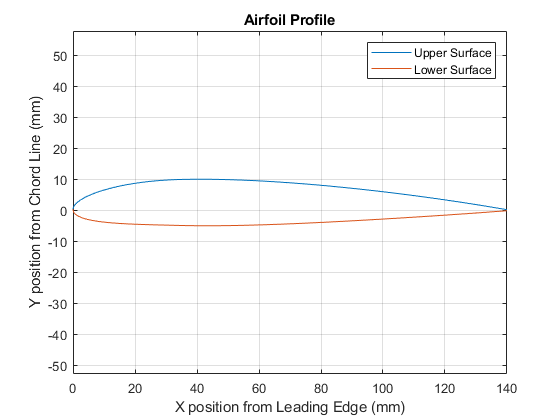

chord = 140;
airfoilData = X1_AirfoilGen(chord);
plot(airfoilData.xU*chord,airfoilData.yU*chord,airfoilData.xL*chord,airfoilData.yL*chord);
grid on
axis equal
title('Airfoil Profile')
xlabel('X position from Leading Edge (mm)')
ylabel('Y position from Chord Line (mm)')
legend('Upper Surface','Lower Surface')

With the functionality now down to one variable, we can move on to determining the aerodynamic properties of the airfoil using Xfoil.

### **Get Coefficients of Lift and Drag (using Xfoil)**

### **[NEED QUICK SUMMARY OF XFOIL]**

Doing some research, I was able to find this [Xfoil interface MATLAB script](https://www.mathworks.com/matlabcentral/fileexchange/49706-xfoil-interface-updated) which made the use of Xfoil much easier and simpler. It requires 4 inputs:

- Coordinates of the upper and lower surface of the airfoil

- Angle of Attack (alpha) [either one or a series of Angles of Attack]

- Reynolds Number (Re)

- Mach Number (M)